# Laboratorium 6

Tadeusz Chmielik 324856

Piotr Sienkiewicz 324887 

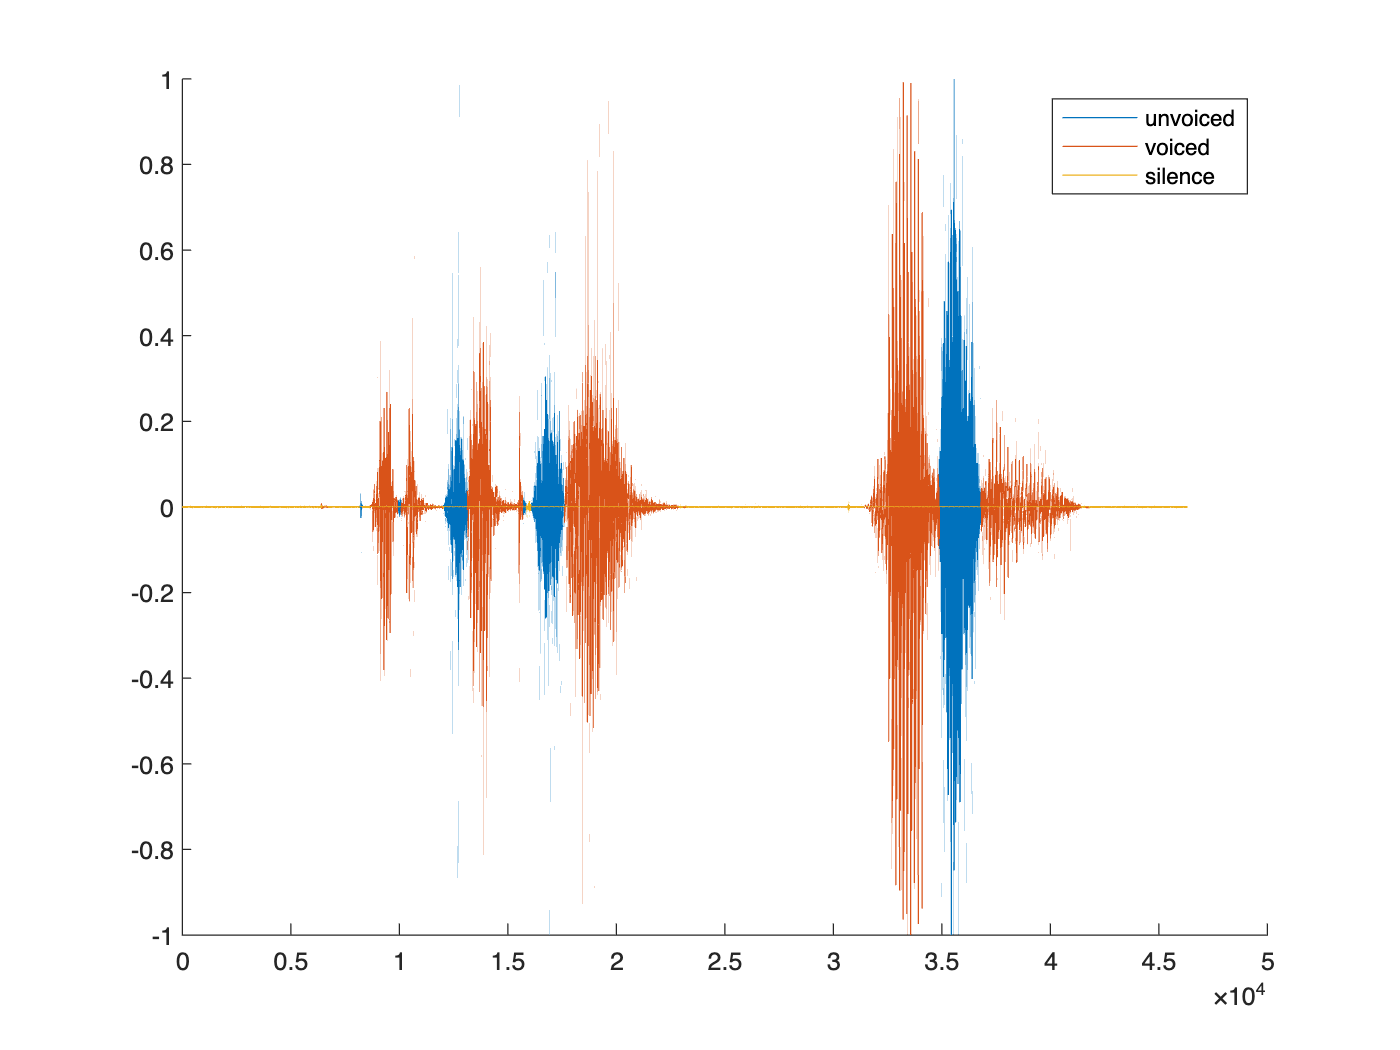

[x, fs] = audioread("percepcja.wav");
x = x / max(x);

lbls = label(x, fs);
f0 = pitchwin(x, fs, round(fs * 0.1));
f0(lbls ~= 2) = 0;

silence = x;
silence(lbls ~= 0) = 0;

unvoiced = x;
unvoiced(lbls ~= 1) = 0;

voiced = x;
voiced(lbls ~= 2) = 0;

figure;
hold on;
plot(unvoiced);
plot(voiced);
plot(silence);
ylim([-1, 1]);
legend("unvoiced", "voiced", "silence");

Częstotliwości bazowe:

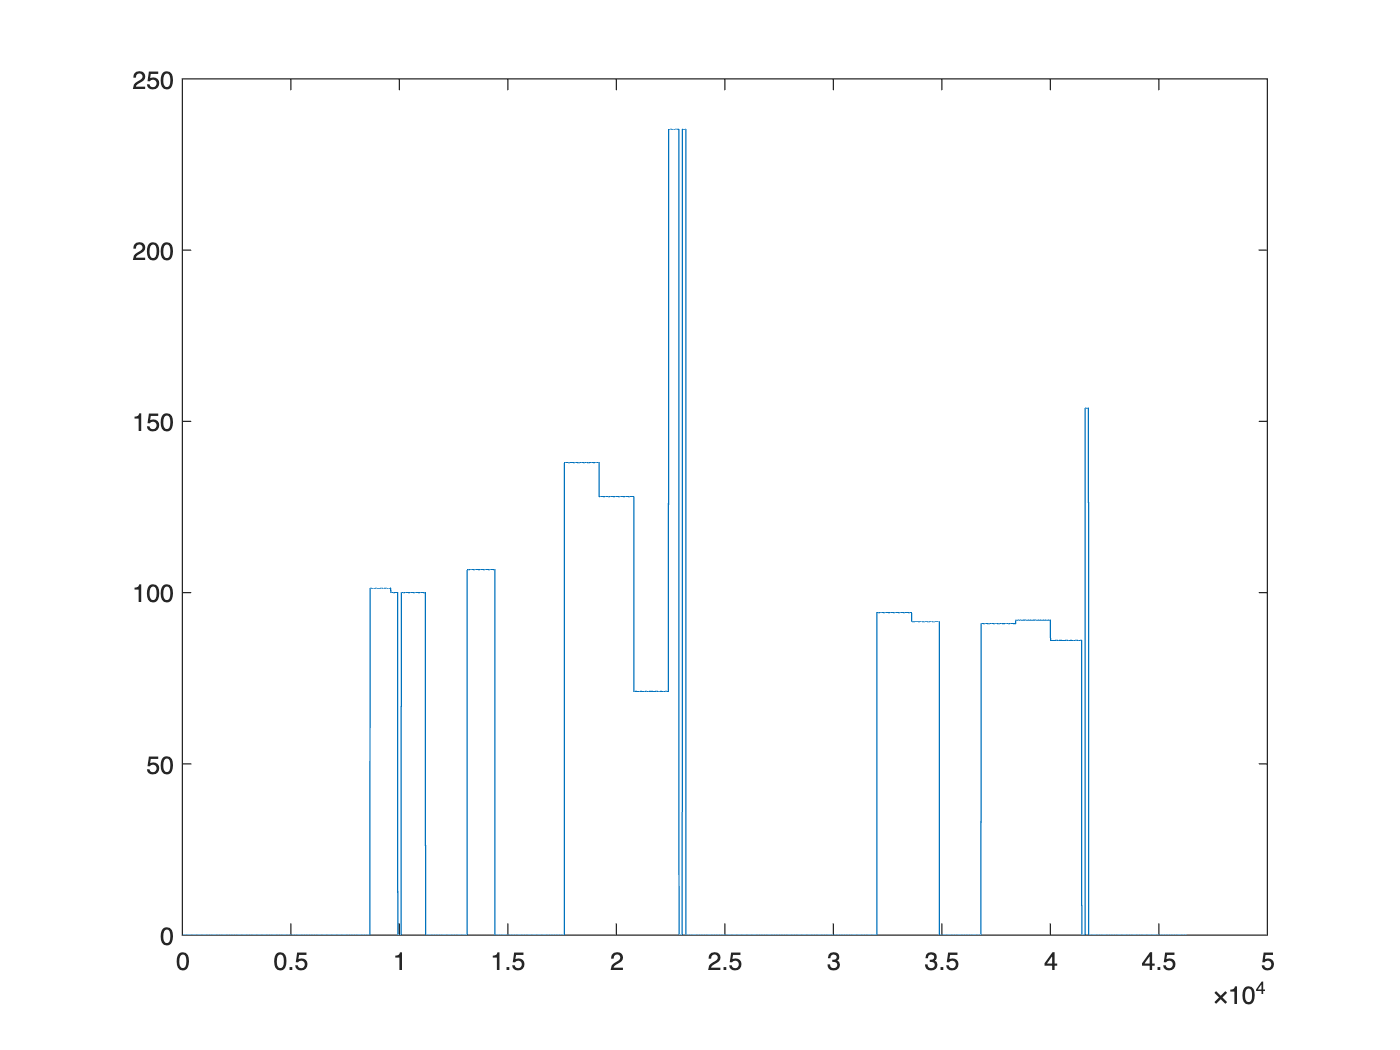

figure;
plot(f0);

Zaimplementowano funkcję określącą częstotliwości bazowe dla poszczególnych okien. Zgodnie z oczekiwaniami poszczególne częstotliwości przyjmowały wartości bliskie 100 Hz. Widoczne na wykresie szpilki odzielające fragmenty nagrania głosu i ciszy wynikają z niedoskonałości użytej metod korelacji. 

function f0 = pitchwin(x, fs, win)

    num_windows = floor(length(x) / win);
    f_win = zeros(1, num_windows);
    f0 = zeros(1,length(x));

    for i = 1:num_windows
        segment = x((i-1)*win + 1 : i*win); 
        f_max = 300;
        lag_min = fs / f_max;
        
        [c, lags] = xcorr(segment, "normalized");
        c = c(lags > lag_min);
        lags = lags(lags > lag_min);
        [pks, loc] = findpeaks(c, "MinPeakProminence", 0.2, "MinPeakWidth", 3);

        if length(loc) >= 2
            [~, index] = max(pks); 
            f_win(i) =  fs / lags(loc(index));
        end
    end

    for i = 1:num_windows
        start_idx = (i-1) * win + 1;
        end_idx = i * win;
       
        f0(start_idx:end_idx) = f_win(i); 

    end

    

end

Następnie  zaimplementowano funkcję zwracającą etykiety dla kolejnych próbek sygnału. Fragmenty ciszy zawierające jedynie szum są wykrywane za  pomocą metody mierzącej chwilową energię sygnału, natomiast głoski dźwięczne i bezdźwięczne po częstotści przecinania wartości zero przez sygnał w danym oknie. 

function lbls = label(x, fs)
    
    win = round(fs * 0.01);
    
    ste = conv(x.^2, ones(1,win), 'same');
    ste = ste / max(ste); 
    
    str = sqrt(ste);

    lbls = zeros(1, length(str));
    lbls(str > 0.01) = 1;  


    num_windows = floor(length(x) / win); 
    
    zcr_values = zeros(1, num_windows); 
    
    for i = 1:num_windows
        segment = x((i-1)*win + 1 : i*win); 
        zcr_values(i) = zerocrossrate(segment);
    end
    
    zcr_threshold = 0.3; 

    for i = 1:num_windows
        start_idx = (i-1) * win + 1;
        end_idx = i * win;
        
        if zcr_values(i) < zcr_threshold
            lbls(start_idx:end_idx) = 2; 
        end
    end
end
